data = readtable('data/data1/CHID46.csv');
disp(data);

    dpi    log_vRNA
    ___    ________

    13      4.0378 
    16      5.0338 
    20      5.9031 
    23      5.9649 
    27       5.532 
    30       4.891 
    36        4.44 
    38      4.1673 
    43      4.2634 



h = 0.01;
time = 0:h:80; 
init = [10^4 0 10^-3];
tau = 7;
c = 23;

xx = [4.09*(10^-7),0.233*10^-6, 0.249,0.775,14.5*10^3,0.03]; %% param in paper

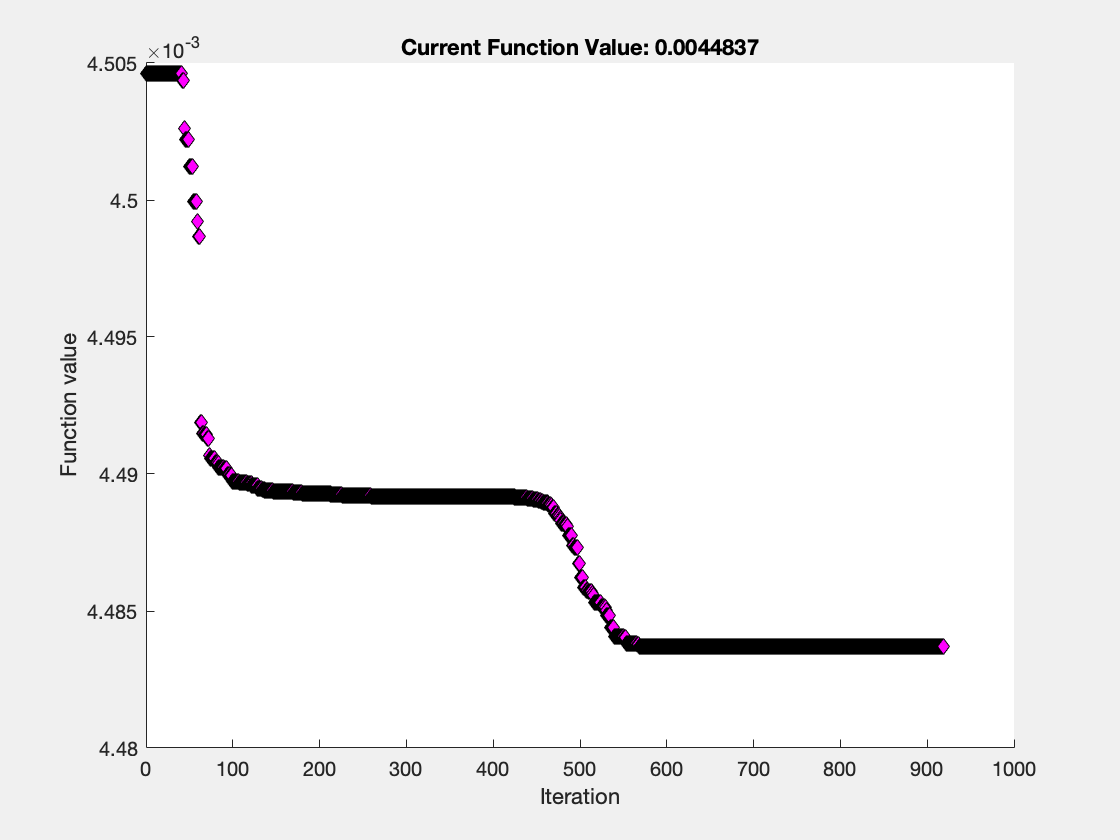

JJ = @(param) J(param, data, h,time,init,tau,c);

options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);

% x0 = [4.0*(10^-7),0.20*10^-6, 0.20,0.70,14.0*10^3,0.03];
x0 = [2.0187*(10^-7),1.2535*(10^-7),1.42261,1.56561,42.77631622*(10^3),0.03931];
x = fminsearch(JJ,x0,options);

x

x = 1.0e+04 *

    0.0000    0.0000    0.0001    0.0002    4.2408    0.0000



% +-10% error

x(1)

ans = 4.2603e-07

plot(time, pred_logV(x,time,init, 7,23), ...
    time,pred_logV(x0,time,init, 7,23), ...
    time,pred_logV(xx,time,init, 7,23))

disp([JJ(x),JJ(x0),JJ(xx)]);

    0.0045    0.0045    0.0079



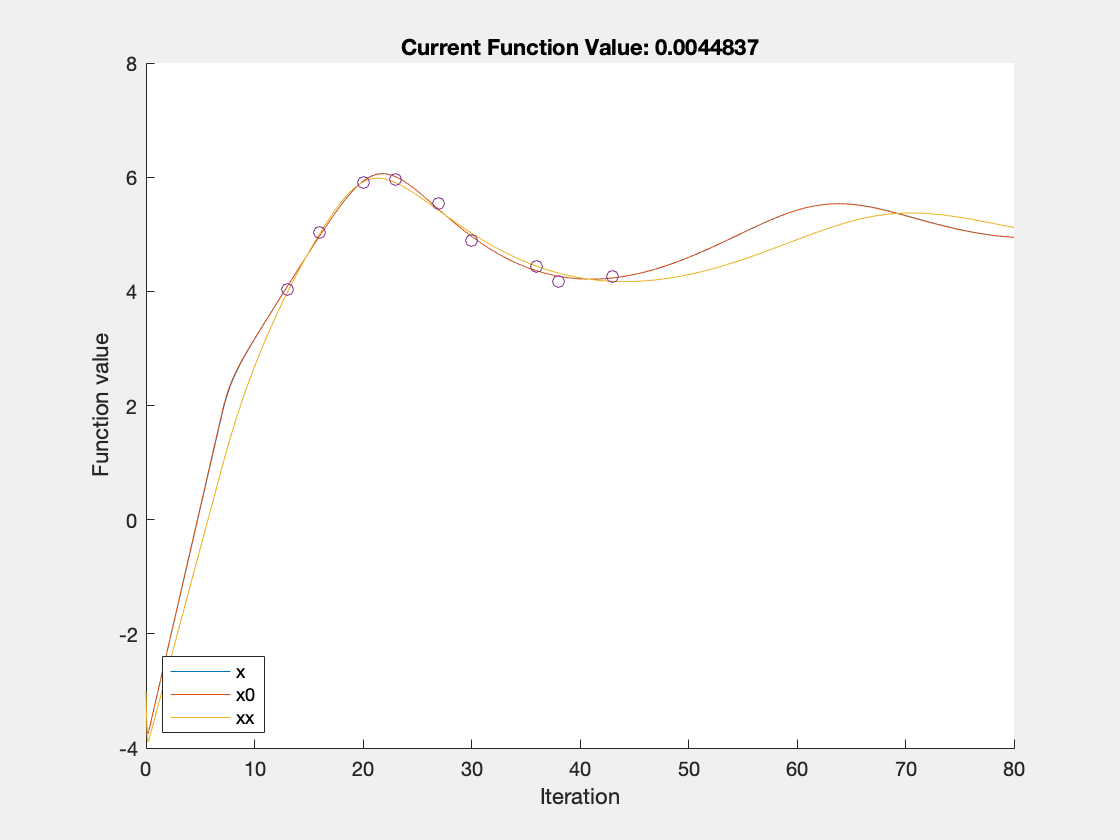

hold on;
scatter(data.dpi,data.log_vRNA);
hold off;
legend({'x','x0','xx'},'Location','southwest')

plot(time, pred_logV(x,time,init, 7,23), ...
    time,pred_logV(x0,time,init, 7,23))

disp([JJ(x),JJ(x0)]);

    0.0045    0.0045



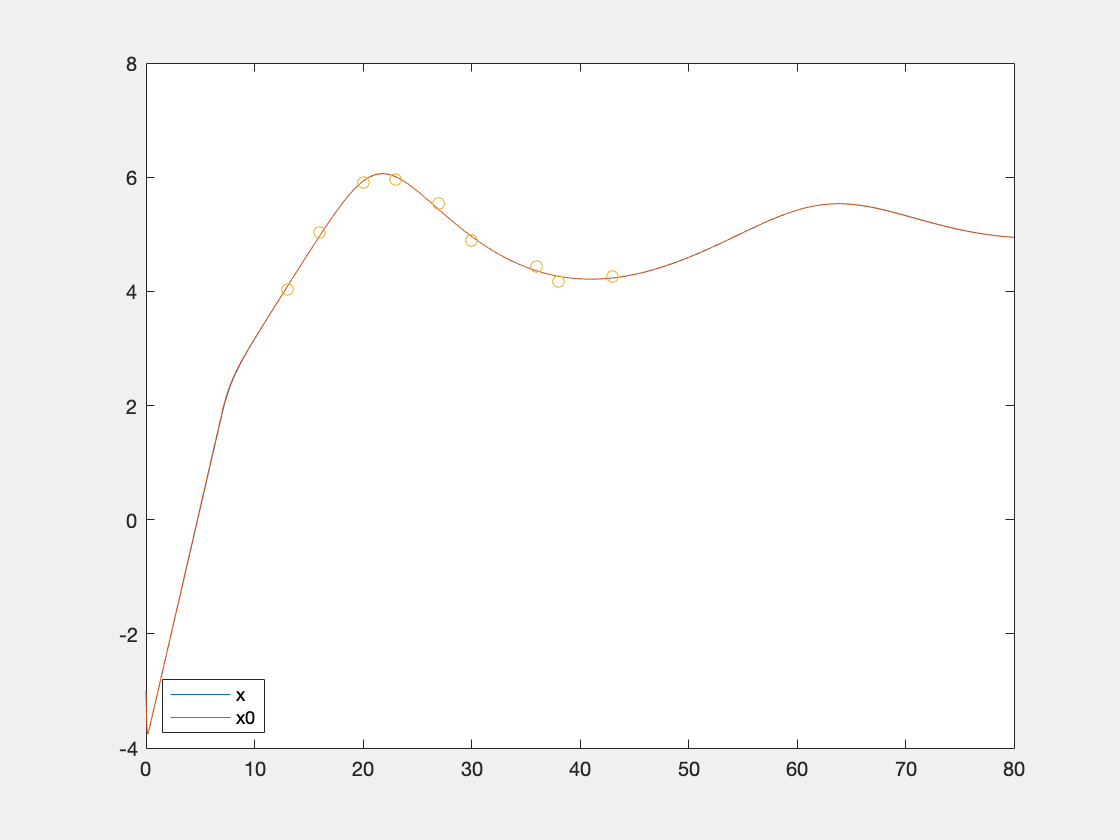

hold on;
scatter(data.dpi,data.log_vRNA);
hold off;
legend({'x','x0'},'Location','southwest')

function out=beta(t,tau,k,beta_0,beta_ifty)
    if t <= tau
        out = beta_0;
    else
        out = beta_ifty+(beta_0-beta_ifty)*exp(-k*(t-tau));
    end
end


function out = pred_logV(param, time, init, tau,c)
    beta_0=param(1);
    beta_ifty=param(2);
    k = param(3);
    dlt = param(4);
    p = param(5);
    d = param(6);
    
    f = @(t,x) [d*(10^4-x(1))-beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3);...
            beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-c*x(3) ];
  
    [t,xa] = ode45(f,time,init);
    out = log10(xa(:,3));
    
end


function out=J(param,data,h,time,init,tau,c)
    pred = pred_logV(param, time, init, tau,c);

    num = size(data,1);
    sum = 0;
    for i = 1:num
        day = data.dpi(i);
        pred_logv = pred(day/h+1);
        
        sum = sum + (pred_logv - data.log_vRNA(i))^2;
    end 
    
   out = sum/num;
end 
